# EE4530 Applied Convex Optimization mini-Project - SVM

## Clear all

clear all;
clc;
close all;

## 1. Data Load

load("linear_svm.mat");

### Data Exploration

Take a look at the distribution of the data

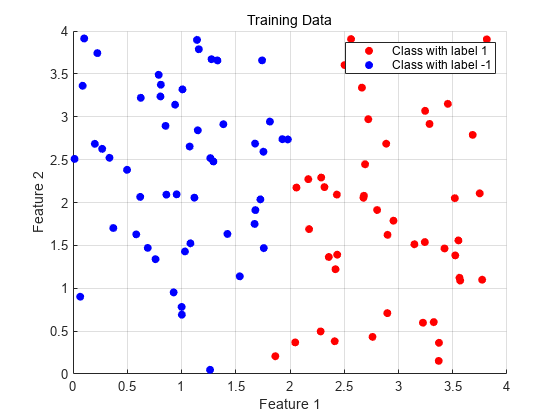

% plot the training data
figure;

% plot data with label = 1
scatter(X_train(labels_train == 1, 1), X_train(labels_train == 1, 2), 'ro', 'filled');
hold on;

% plot data with label = -1
scatter(X_train(labels_train == -1, 1), X_train(labels_train == -1, 2), 'bo', 'filled');

title('Training Data');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class with label 1', 'Class with label -1');

% display
grid on;
% axis padded;
hold off;

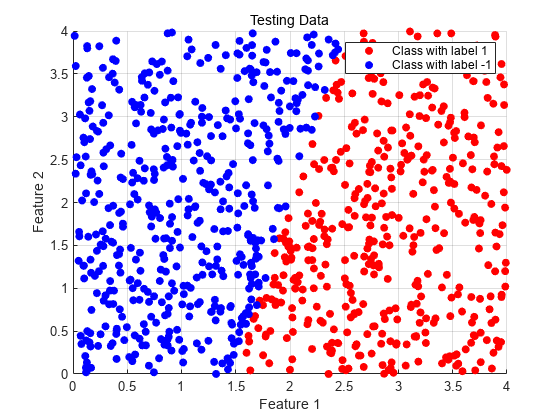

% plot the testing data
figure;

% plot data with label=1
scatter(X_test(labels_test == 1, 1), X_test(labels_test == 1, 2), 'ro', 'filled');
hold on;

% plot data with label=-1
scatter(X_test(labels_test == -1, 1), X_test(labels_test == -1, 2), 'bo', 'filled');

title('Testing Data');
xlabel('Feature 1');
ylabel('Feature 2');
legend('Class with label 1', 'Class with label -1');

% display
grid on;
hold off;

## 1.Task 1

硬约束: svm最优化目标为最大化决策边界, 转化为下面的公式


$$\min_{\vec{w}} f(\vec{w})=\frac{||\vec{w}||^2}{2} \\
\text{s.t.}  \ g_i(\vec{w}, b) = y_i \cdot(\vec{w}\cdot \vec{x_i} + b) \geq 1

$$


[N_train, n] = size(X_train);
[N_test, n] = size(X_test);

tic;        % 运算时长
% Convex计算
cvx_begin
    variables w(n) b;
    % 目标
    minimize(0.5 * w' * w);

    % 约束条件
    subject to
        for i = 1:N_train
            labels_train(i) * (X_train(i, :) * w + b) >= 1;
        end
cvx_end

 
Calling SDPT3 4.0: 104 variables, 4 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  4
 dim. of socp   var  =  4,   num. of socp blk  =  1
 dim. of linear var  = 100
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.7e+02|2.4e+01|5.0e+04|-2.000000e+03  0.000000e+00| 0:0:00| chol  1  1 
 1|0.410|0.416|5.7e+02|1.4e+01|4.0e+04|-1.397413e+03 -7.987107e+01| 0:0:00| chol  1  1 
 2|0.300|0.326|4.0e+02|9.3e+00|3.5e+04|-9.280953e+02 -2.648473e+02| 0:0:00| chol  1  1 
 3|0.202|0.255|3.2e+02|7.0e+00|3.3e+

time = toc;

fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f", w(1), w(2), b, time);

Optimal w: (11.255635, -1.973901)'
Optimal b: -17.888523
Running time: 1.116507

y_pre = svm_predict(w, b, X_test);
accuracy = svm_report(labels_test, y_pre);
fprintf("Test Acc: %f", accuracy);

Test Acc: 0.976667

## 2. Task 2

% data preprocessing
X_train_normalized = normalize(normalize(X_train), "range");
X_test_normalized = normalize(normalize(X_test), "range");

% 超参数
lambda = 0.01;
t = 0.01;
num_iters = 10000;


## Method 1: SGD

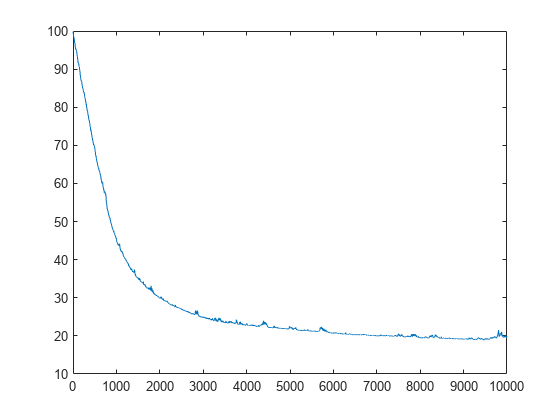


% 训练 SVM
tic;
[w, b, w_list_gd, b_list_gd, errors_gd] = svm_gd(X_train_normalized, labels_train, lambda, t, num_iters);
time = toc;
figure(1);
plot(errors_gd);

fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f", w(1), w(2), b, time);

Optimal w: (4.411071, -0.759318)'
Optimal b: -1.990000
Running time: 0.027842

y_pre = svm_predict(w, b, X_test_normalized);
accuracy = svm_report(labels_test, y_pre);
fprintf("Test Acc: %f", accuracy);

Test Acc: 0.948889

## Method 2: BLS


% 超参数
% num_iters = 1000;
alpha = 0.25;
beta = 0.5;
t0 = 0.01;

% 训练 SVM
tic;
[w, b, iter, w_list, b_list, errors_bls] = svm_bls(X_train_normalized, labels_train, lambda, num_iters, alpha, beta, t0);

    0.0078



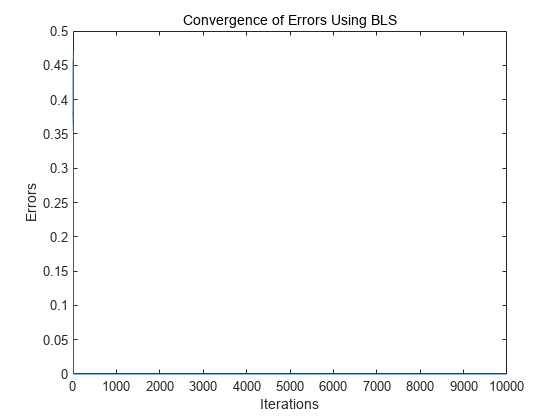

figure(2);
plot(errors_bls);
title("Convergence of Errors Using BLS");
xlabel("Iterations");
ylabel("Errors");

time_bls = toc;

% 显示结果
fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f\nNumber of iteration: %d", ...
    w(1), w(2), b, time_bls, iter);

Optimal w: (5.170825, -0.585432)'
Optimal b: -2.328125
Running time: 0.043201
Number of iteration: 13

y_pre = svm_predict(w, b, X_test_normalized);
accuracy = svm_report(labels_test, y_pre);
fprintf("Test Acc: %f", accuracy); 

Test Acc: 0.955556

## Opt: Lag

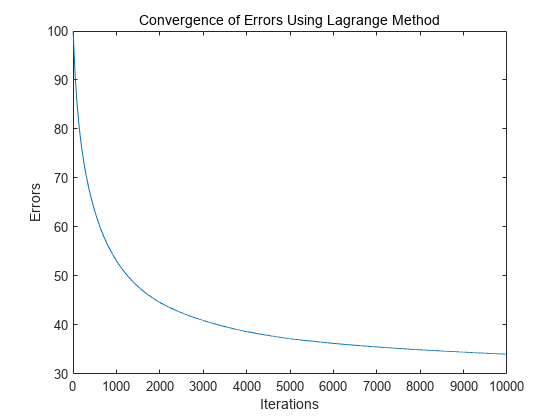


tic;
lr = 0.01;
[w, b, alpha, w_list_lg, b_list_lg, errors_lg] = svm_lag(X_train_normalized, labels_train, lr, num_iters);
time_lag = toc;
y_pre = svm_predict(w, b, X_test_normalized);
accuracy = svm_report(labels_test, y_pre);
figure(3);
plot(errors_lg);
title("Convergence of Errors Using Lagrange Method");
xlabel("Iterations");
ylabel("Errors");

fprintf("Test Acc: %f", accuracy); 

Test Acc: 0.966667

fprintf("Training Time: %f", time_lag);

Training Time: 0.075755

fprintf("Optimal w: (%f, %f)'\nOptimal b: %f\nRunning time: %f", w(1), w(2), b, time);

Optimal w: (3.150060, -1.048017)'
Optimal b: -1.032888
Running time: 0.027842